# 提取信号幅度差

## 读取文件

clear
close all
% 文件路径
% 315
% dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压';
% 203
dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\0612测试集_3Tag_35Point\Tag2_Loc11';

FileTable = [
'P01_150mV_100mV_Tag2_gnss_log_2021_06_12_17_13_53.txt';
'P01_150mV_100mV_Tag2_gnss_log_2021_06_12_17_32_33.txt';
'P02_150mV_100mV_Tag2_gnss_log_2021_06_12_17_44_16.txt';
'P03_150mV_100mV_Tag2_gnss_log_2021_06_12_18_01_51.txt';
'P04_150mV_100mV_Tag2_gnss_log_2021_06_12_18_35_51.txt';
'P05_150mV_100mV_Tag2_gnss_log_2021_06_12_18_46_52.txt';
'P06_150mV_100mV_Tag2_gnss_log_2021_06_12_17_50_41.txt';
'P06_150mv_100mV_Tag2_gnss_log_2021_06_12_18_59_13.txt';
'P07_150mV_100mV_Tag2_gnss_log_2021_06_12_18_01_46.txt';
'P07_150mV_100mV_Tag2_gnss_log_2021_06_12_19_10_10.txt';
'P08_150mV_100mV_Tag2_gnss_log_2021_06_12_19_33_19.txt';
'P08_150mV_100mV_Tag2_gnss_log_2021_06_12_19_58_04.txt';
'P09_150mV_100mV_Tag2_gnss_log_2021_06_12_20_09_05.txt';
'P09_150mV_100mV_Tag2_gnss_log_2021_06_12_20_54_12.txt';
'P10_152mV_100mV_Tag2_gnss_log_2021_06_12_21_04_39.txt';
'P12_150mV_100mV_Tag2_gnss_log_2021_06_12_21_15_30.txt';
'P13_150mV_100mV_Tag2_gnss_log_2021_06_12_21_25_55.txt';
'P14_150mV_100mV_Tag2_gnss_log_2021_06_12_21_36_49.txt';
'P15_150mV_100mV_Tag2_gnss_log_2021_06_12_21_48_25.txt';
'P16_150mV_100mV_Tag2_gnss_log_2021_06_12_22_10_28.txt';
'P16_150mV_100mV_Tag2_gnss_log_2021_06_12_22_23_55.txt';
'P17_150mV_100mV_Tag2_gnss_log_2021_06_12_22_34_52.txt';
'P18_150mV_100mV_Tag2_gnss_log_2021_06_12_22_45_33.txt';
'P19_150mV_100mV_Tag2_gnss_log_2021_06_12_22_56_08.txt';
'P20_150mV_100mV_Tag2_gnss_log_2021_06_12_23_06_39.txt';
'P21_150mV_100mV_Tag2_gnss_log_2021_06_13_20_17_14.txt';
'P21_150mV_100mV_Tag2_gnss_log_2021_06_13_20_28_42.txt';
'P22_150mV_100mV_Tag2_gnss_log_2021_06_13_20_39_21.txt';
'P23_150mV_100mV_Tag2_gnss_log_2021_06_13_20_50_35.txt';
'P24_150mV_100mV_Tag2_gnss_log_2021_06_13_21_01_53.txt';
'P25_150mV_100mV_Tag2_gnss_log_2021_06_13_21_13_45.txt';
'P26_150mV_100mV_Tag2_gnss_log_2021_06_13_21_25_00.txt';
'P27_150mV_100mV_Tag2_gnss_log_2021_06_13_21_37_08.txt';
'P28_150mV_100mV_Tag2_gnss_log_2021_06_13_21_49_03.txt';
'P28_150mV_100mV_Tag2_gnss_log_2021_06_14_17_26_41.txt';
'P29_150mV_100mV_Tag2_gnss_log_2021_06_13_22_09_41.txt';
'P29_150mV_100mV_Tag2_gnss_log_2021_06_14_17_15_42.txt';
'P30_150mV_100mV_Tag2_gnss_log_2021_06_14_15_13_24.txt';
'P30_150mV_100mV_Tag2_gnss_log_2021_06_14_15_24_38.txt';
'P30_150mV_100mV_Tag2_gnss_log_2021_06_14_17_04_51.txt';
'P31_150mV_100mV_Tag2_gnss_log_2021_06_14_15_42_07.txt';
'P32_150mV_100mV_Tag2_gnss_log_2021_06_14_15_53_50.txt';
'P33_150mV_100mV_Tag2_gnss_log_2021_06_14_16_31_26.txt';
'P34_150mV_100mV_Tag2_gnss_log_2021_06_14_16_42_18.txt';
'P35_150mV_100mV_Tag2_gnss_log_2021_06_14_16_54_20.txt';  
];
Nfile = size(FileTable,1); 



## 解析文件名中的信息

NnameEle = 12;
Nnum = 10;
FileProperty = zeros(Nfile,Nnum);
for j=1:Nfile
    iNum = 1;
    fileName = FileTable(j,:);
    a = strsplit(fileName,'_');
    for i=1:NnameEle
        str = a{i};
        if ~isempty(find(isstrprop(str,'digit'),1))
            FileProperty(j,iNum) = str2double(str(isstrprop(str,'digit')));
            iNum = iNum + 1;
        end
    end
end
iPoint = 1; iV1 = 2; iV2 = 3; iTag = 4; iYear = 5; iMonth = 6; iDay = 7;
iHour = 8; iMin = 9; iSec = 10; iDate = 5;

## 文件读取控制

% 循环读取
gnssAmplitude = zeros(Nfile,3*5);
for iFile = 1:Nfile
% prFileName = 'P12_150mV_100mV_Tag2_gnss_log_2021_06_12_21_15_30.txt';
prFileName = FileTable(iFile, :);

## 绘制载噪比


Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\C12ES\0728测试\TagLoc2_PN/P9_150mV_gnss_log_2021_07_28_17_18_15.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 417 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s


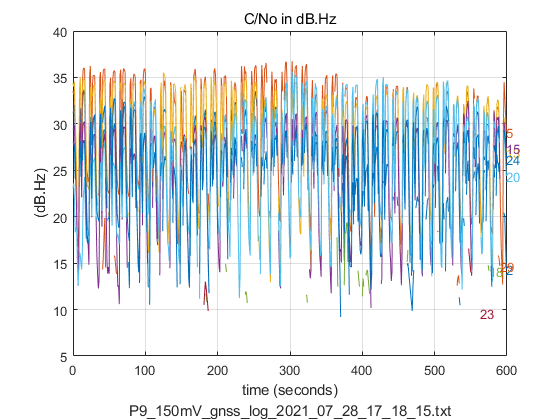

% Set the data filter and Read log file
% prFileName = 'P13_150mV_100mV_Tag2_gnss_log_2021_06_12_21_25_55.txt';
dataFilter = SetDataFilter;
% dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\C12ES\0728测试\TagLoc2_PN';
% prFileName = 'P9_150mV_gnss_log_2021_07_28_17_18_15.txt';
[gnssRaw,gnssAnalysis] = ReadGnssLogger(dirName,prFileName,dataFilter);
if isempty(gnssRaw)
    continue
%     return, 
end

%% process raw measurements, compute pseudoranges:
[gnssMeas]= ProcessGnssMeasForBackscatter(gnssRaw);

%% plot pseudoranges and pseudorange rates
h1 = figure;
% [colors] = PlotPseudoranges(gnssMeas,prFileName);
% h2 = figure;
% PlotPseudorangeRates(gnssMeas,prFileName,colors);
% h3 = figure;
% PlotCno(gnssMeas,prFileName,colors);
colors = PlotCno(gnssMeas,prFileName);

## 提取最强信号

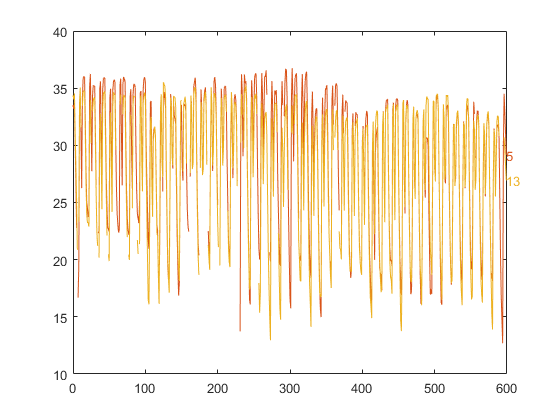

% 信号持续时间长，强度大，选取整个采样时段内平均值最强的信号
M = length(gnssMeas.Svid);
N = length(gnssMeas.FctSeconds);
iNan = find(isnan(gnssMeas.Cn0DbHz));
Cn0iDbHz = gnssMeas.Cn0DbHz;
Cn0iDbHz(iNan) = 0;
Ecn0 = mean(Cn0iDbHz);
[Esort,iMax] = sort(Ecn0,'descend');

Nmax = 2;
timeSeconds = gnssMeas.FctSeconds-gnssMeas.FctSeconds(1);% elapsed time in seconds
figure
for i=1:Nmax
    Cn0iDbHz = gnssMeas.Cn0DbHz(:,iMax(i));
    iF = find(isfinite(Cn0iDbHz));
    if ~isempty(iF)
        ti = timeSeconds(iF(end));
        h = plot(timeSeconds,Cn0iDbHz);
        hold on
        set(h,'Color',colors(iMax(i),:));
        ts = int2str(gnssMeas.Svid(iMax(i)));
        text(ti,Cn0iDbHz(iF(end)),ts,'Color',colors(iMax(i),:));
    end
end

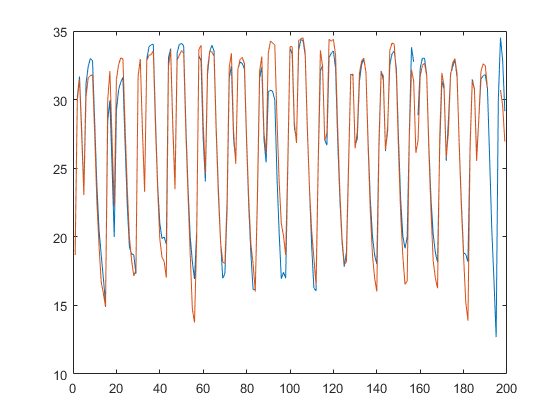

Cn0iDbHz = gnssMeas.Cn0DbHz(:, [iMax(1) iMax(2)]);
% 论文用图
% figure
% plot(Cn0iDbHz(400:end,:));

## 计算强信号的幅度均值

% 根据信号强度分离出两条路径
trend = [ smooth(Cn0iDbHz(:,1), 21) smooth(Cn0iDbHz(:,2), 21)];
gnssCn0Extract = Cn0iDbHz - trend;
figure
plot(gnssCn0Extract)

iNan = find(isnan(gnssCn0Extract));
Cn0Extract = gnssCn0Extract;
Cn0Extract(iNan) = 0;
% pickUp -> backscattered sat signal  BKS
% pickDn -> original sat signal       NBKS
pickUp = zeros(N, Nmax);
pickDn = zeros(N, Nmax);
CnoSmooth = [smooth(Cn0Extract(:,1), 7) smooth(Cn0Extract(:,2), 7)];
for i=1:N
    for j=1:Nmax
        if isfinite(gnssCn0Extract(i,j)) 
            if Cn0Extract(i,j) > CnoSmooth(i,j)
                pickUp(i,j) = 1;
            else
                pickDn(i,j) = 1;
            end
        end
    end
end

% plot to check seperation
gnssMeaSep.iBks_1 = find(pickUp(:,1) == 1);
gnssMeaSep.iBks_2 = find(pickUp(:,2) == 1);
gnssMeasSep.Bks = pickUp .* Cn0Extract;
gnssMeaSep.iOrg_1 = find(pickDn(:,1) == 1); 
gnssMeaSep.iOrg_2 = find(pickDn(:,2) == 1);
gnssMeasSep.Org = pickDn .* Cn0Extract;
gnssMeasSep.smooth = CnoSmooth;

% 画出分类结果
figure
subplot(3,1,1)
h = plot(Cn0Extract);
colors = get(h,'Color');
subplot(3,1,2)
plot(Cn0Extract(:,1),'-*','Color',colors{1},'MarkerIndices',gnssMeaSep.iBks_1,'MarkerEdgeColor','r');
hold on
plot(gnssMeasSep.smooth(:,1),'c-')
plot(Cn0Extract(:,1),'-*','Color',colors{1},'MarkerIndices',gnssMeaSep.iOrg_1,'MarkerEdgeColor','g');
hold off

subplot(3,1,3)
plot(Cn0Extract(:,2),'-*','Color',colors{2},'MarkerIndices',gnssMeaSep.iBks_2,'MarkerEdgeColor','r');
hold on
plot(gnssMeasSep.smooth(:,2),'c-')
plot(Cn0Extract(:,2),'-*','Color',colors{2},'MarkerIndices',gnssMeaSep.iOrg_2,'MarkerEdgeColor','g');
hold off

% close all

% 论文用图 P35
% figure
% h=plot(Cn0Extract(201:400,:),'LineWidth',1.5);
% colors = get(h,'Color');
% hold on
% plot(Cn0Extract(201:400,1),'Marker','square','MarkerSize',3,'LineWidth',1.5,'Color',colors{1},'MarkerIndices',gnssMeaSep.iBks_1(115:222)-200,'MarkerEdgeColor','r','MarkerFaceColor','r');
% plot(Cn0Extract(201:400,1),'Marker','square','MarkerSize',3,'LineWidth',1.5,'Color',colors{1},'MarkerIndices',gnssMeaSep.iOrg_1(87:177)-200,'MarkerEdgeColor','b','MarkerFaceColor','b');
% hold off

% % 论文用图 PN
% figure
% h=plot(Cn0Extract(400:end,:),'LineWidth',1.5);
% colors = get(h,'Color');
% hold on
% plot(Cn0Extract(400:end,1),'Marker','square','MarkerSize',3,'LineWidth',1.5,'Color',colors{1},'MarkerIndices',gnssMeaSep.iBks_1(206:end)-399,'MarkerEdgeColor','r','MarkerFaceColor','r');
% plot(Cn0Extract(400:end,1),'Marker','square','MarkerSize',3,'LineWidth',1.5,'Color',colors{1},'MarkerIndices',gnssMeaSep.iOrg_1(171:end)-399,'MarkerEdgeColor','b','MarkerFaceColor','b');
% hold off


% 求出幅度均值
% Amplitude = zeros(1,2);
% Amplitude(1) = mean(gnssMeasSep.Bks(gnssMeaSep.iBks_1,1)) - mean(gnssMeasSep.Org(gnssMeaSep.iOrg_1,1));
% Amplitude(2) = mean(gnssMeasSep.Bks(gnssMeaSep.iBks_2,2)) - mean(gnssMeasSep.Org(gnssMeaSep.iOrg_2,2));

% 分割成五段，得到五个均值扩展
Amplitude = zeros(2,5);
NBksSeg = [floor(length(gnssMeaSep.iBks_1)/5) floor(length(gnssMeaSep.iBks_2)/5)];
NOrgSeg = [floor(length(gnssMeaSep.iOrg_1)/5) floor(length(gnssMeaSep.iOrg_2)/5)];

Amplitude(1,:) = mean(reshape(gnssMeasSep.Bks(gnssMeaSep.iBks_1(1:NBksSeg(1)*5),1),  NBksSeg(1),[])) ...
    - mean(reshape(gnssMeasSep.Org(gnssMeaSep.iOrg_1(1:NOrgSeg(1)*5),1),  NOrgSeg(1), []));
Amplitude(2,:) = mean(reshape(gnssMeasSep.Bks(gnssMeaSep.iBks_2(1:NBksSeg(2)*5),2),  NBksSeg(2),[])) ...
    - mean(reshape(gnssMeasSep.Org(gnssMeaSep.iOrg_2(1:NOrgSeg(2)*5),2),  NOrgSeg(2), []));



gnssAmplitude(iFile,:) = [reshape(Amplitude',1,[]) mean(Amplitude)];
end

% gnssAmplitude = mean(Amplitude);
 gnssDataRaw = [FileProperty gnssAmplitude];

## 计算各点到 tag 的距离

x = 1:7;
x = repmat(x,5,1);
% x = x(:);
y = 1:5;
y = repmat(y',1,7);
% y = y(:);
corxy = [x(:) y(:)];
tagxy = [3 1];
disxy = corxy - tagxy;
distant2tag = 2.5 * sqrt(sum(disxy.^2,2));

## 画出距离与幅度的曲线图

% 拼接距离到幅度信息上
gnssData = zeros(Nfile,size(gnssDataRaw,2)+1);
iValid = 1;
for i=1:Nfile
    if gnssDataRaw(i,end) ~= zeros(1,5)
        gnssData(iValid,:) = [gnssDataRaw(i,:) distant2tag(gnssDataRaw(i,1))]; 
        iValid = iValid + 1;
    end
end
gnssData = gnssData(1:iValid-1,:);




figure
plot(gnssData(:,size(gnssData,2)), gnssData(:,size(gnssData,2)-1), '+')
hold on
plot(gnssData(:,size(gnssData,2)), gnssData(:,size(gnssData,2)-2), '+')
plot(gnssData(:,size(gnssData,2)), gnssData(:,size(gnssData,2)-3), '+')
plot(gnssData(:,size(gnssData,2)), gnssData(:,size(gnssData,2)-4), '+')
plot(gnssData(:,size(gnssData,2)), gnssData(:,size(gnssData,2)-5), '+')
hold off

Nvalid = size(gnssData,1);
% choose = [1 2 7 8 9 10 14 18 19 24 31 37];
% choose = [1 2 7 8 22 27 33];
% choose = 1:6;
% plot(gnssData(choose,size(gnssData,2)), gnssData(choose,size(gnssData,2)-1), 'r+')



